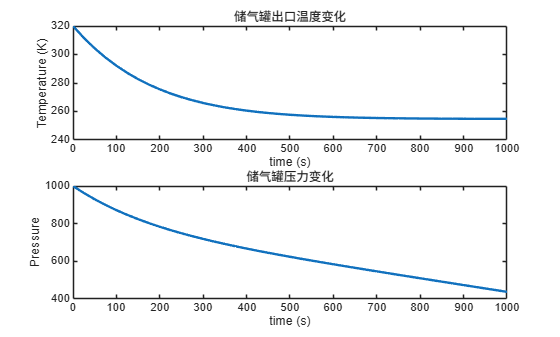

clear; clc;

% ---------------------- 参数设定 ----------------------
param.R    = 0.287;     % kJ/kg·K 
param.V    = 100;       % m^3
param.h    = 0.025;     % 换热系数
param.A    = 150;       % 换热面积 m^2
param.Tamb = 288;       % 环境温度
param.mdot = 0.49;      % 出口质量流量 kg/s(无法确定质量流量时，可通过膨胀机入口压力与储气罐内压比值计算）

% ---------------------- 初始条件 ----------------------
T0 = 320;               % 初始温度 K
P0 = 1000;              % 初始压力（任意单位）
                        % 用 P = mRT/V 求初始质量
m0 = P0 * param.V / (param.R * T0);

X0 = [T0; m0];

% ---------------------- 求解 ODE ----------------------
tspan = [0 1000];
[t, X] = ode45(@(t,X) Gas_storage_tank_output(t, X, param), tspan, X0);

T = X(:,1);
m = X(:,2);
P = m .* param.R .* T ./ param.V;

% ---------------------- 结果可视化 ---------------------
figure;
subplot(2,1,1)
plot(t, T, 'LineWidth',1.8);
xlabel('time (s)'); ylabel('Temperature (K)');
title('储气罐出口温度变化');

subplot(2,1,2)
plot(t, P, 'LineWidth',1.8);
xlabel('time (s)'); ylabel('Pressure');
title('储气罐压力变化');